# Read the original dataset

clc; clear;

% Define all paths
currentDir = 'C:\Users\61946\Desktop\CollaborativeFiltering';
rawDataDir = strcat(currentDir, '\RawDataset');
functionDir = strcat(currentDir, '\Functions');
targetDir = strcat(currentDir, '\AllResults\EffectofT')

targetDir = 'C:\Users\61946\Desktop\CollaborativeFiltering\AllResults\EffectofT'


% Load the IDA results
cd (rawDataDir)
maximum_story_drift = importdata('SMRF-2.csv');
[NGM, NIL] = size(maximum_story_drift.data);

## Define all input parameters

Nf = 20;
lambda = 0.1;
N = 2;
DL = 0.1;

% ----------------- These are for OLD buildings --------------------
% SMRF-1
% SaMCE = 1.22;
% SMRF-2
% SaMCE = 0.81;
% SMRF-3
% SaMCE = 0.51;
% -----------------------------------------------------------------


% ----------------- These are for NEW buildings -------------------
% SMRF-1
% SaMCE = 1.623;
% SMRF-2
SaMCE = 1.078;
% SMRF-3
% SaMCE = 0.673;
% ----------------------------------------------------------------



IDA_scales = [20, 40, 60, 80, 100, 120, 140, 160, 180, 200, 210, 220, 230, 240, 250, 260, 270, 280, 290, 300];

intensityLevels = SaMCE * IDA_scales / 100;

% OLD TList
% TList = [0, 5, 10, 15, 20, 25, 30, 35, 40, 45, 50];
% NEW TList
TList = [0, 5, 10, 15, 20, 25, 30, 35, 40, 45, 50, 55, 60, 65, 70, 75, 80, 85, 90];
% NfList = [10, 20, 30, 40, 50];
% lambdaList = [0.01, 0.05, 0.1, 0.15, 0.2];
% NList = [2,3,4,5,6,7,8];

## Collaborative filtering based collapse fragility assessment:

% Randomness is introduced, so multiple simulations are run here to see the
% overall performance
numberSimulations = 100;

thetaList = zeros([length(TList), numberSimulations]);
betaList = zeros([length(TList), numberSimulations]);

for Tindex = 1:length(TList)
    
    T = TList(Tindex)

    for eachSimulation = 1:numberSimulations

    % 1st module: prepare the matrix P and R
    P = maximum_story_drift.data';
    R = zeros([NIL, NGM]);
    for i = 1:NIL
        for j = 1:NGM
            n = randi(100);
            if n > T
                R(i, j) = 1;
            else
                P(i, j) = -1;
            end
        end
    end
    
    % 2nd module: formulate the collaborative filtering algorithm
    cd(functionDir)
    completePerformanceRating = collaborativeFilteringFun(N, P, R, DL, Nf, lambda);
    
    % 3rd module: fit the empirical collapse probability using lognormal distribution
    % function
    [theta, beta, collapseFractions] = fitLognormalDistribution(completePerformanceRating, intensityLevels);
    
    thetaList(Tindex, eachSimulation) = theta;
    betaList(Tindex, eachSimulation) = beta;

    end
end

T = 0

Iteration     1 | Cost: 8.705688e+02
Iteration     2 | Cost: 2.780599e+02
Iteration     3 | Cost: 1.150923e+02
Iteration     4 | Cost: 7.190456e+01
Iteration     5 | Cost: 5.078820e+01
Iteration     6 | Cost: 4.293808e+01
Iteration     7 | Cost: 3.918400e+01
Iteration     8 | Cost: 3.563920e+01
Iteration     9 | Cost: 3.240736e+01
Iteration    10 | Cost: 3.011574e+01
Iteration    11 | Cost: 2.777833e+01
Iteration    12 | Cost: 2.638223e+01
Iteration    13 | Cost: 2.591382e+01
Iteration    14 | Cost: 2.471148e+01
Iteration    15 | Cost: 2.361349e+01
Iteration    16 | Cost: 2.312619e+01
Iteration    17 | Cost: 2.198867e+01
Iteration    18 | Cost: 2.044781e+01
Iteration    19 | Cost: 1.889684e+01
Iteration    20 | Cost: 1.830024e+01
Iteration    21 | Cost: 1.822508e+01
Iteration    22 | Cost: 1.725012e+01
Iteration    23 | Cost: 1.688292e+01
Iteration    24 | Cost: 1.661390e+01
Iteration    25 | Cost: 1.622588e+01
Iteration    26 | Cost: 1.586479e+01
Iteration    27 | Cost: 1.527920e+01
I

T = 5

Iteration     1 | Cost: 3.434479e+03
Iteration     2 | Cost: 3.584514e+02
Iteration     3 | Cost: 1.897035e+02
Iteration     4 | Cost: 9.747563e+01
Iteration     5 | Cost: 6.568001e+01
Iteration     6 | Cost: 5.685632e+01
Iteration     7 | Cost: 5.124574e+01
Iteration     8 | Cost: 4.833687e+01
Iteration     9 | Cost: 4.734344e+01
Iteration    10 | Cost: 4.342790e+01
Iteration    11 | Cost: 4.151963e+01
Iteration    12 | Cost: 3.976904e+01
Iteration    13 | Cost: 3.758495e+01
Iteration    14 | Cost: 3.571069e+01
Iteration    15 | Cost: 3.417721e+01
Iteration    16 | Cost: 3.317486e+01
Iteration    17 | Cost: 3.180135e+01
Iteration    18 | Cost: 3.110573e+01
Iteration    19 | Cost: 3.072346e+01
Iteration    20 | Cost: 2.992345e+01
Iteration    21 | Cost: 2.919173e+01
Iteration    22 | Cost: 2.846039e+01
Iteration    23 | Cost: 2.726993e+01
Iteration    24 | Cost: 2.613235e+01
Iteration    25 | Cost: 2.568071e+01
Iteration    26 | Cost: 2.558011e+01
Iteration    27 | Cost: 2.473177e+01
I

T = 10

Iteration     1 | Cost: 8.540796e+02
Iteration     2 | Cost: 2.674011e+02
Iteration     3 | Cost: 1.240779e+02
Iteration     4 | Cost: 7.957416e+01
Iteration     5 | Cost: 5.210476e+01
Iteration     6 | Cost: 4.107430e+01
Iteration     7 | Cost: 3.545445e+01
Iteration     8 | Cost: 3.251018e+01
Iteration     9 | Cost: 2.999680e+01
Iteration    10 | Cost: 2.824165e+01
Iteration    11 | Cost: 2.649735e+01
Iteration    12 | Cost: 2.502356e+01
Iteration    13 | Cost: 2.401583e+01
Iteration    14 | Cost: 2.281365e+01
Iteration    15 | Cost: 2.183504e+01
Iteration    16 | Cost: 2.081386e+01
Iteration    17 | Cost: 1.948926e+01
Iteration    18 | Cost: 1.829715e+01
Iteration    19 | Cost: 1.726073e+01
Iteration    20 | Cost: 1.588270e+01
Iteration    21 | Cost: 1.447489e+01
Iteration    22 | Cost: 1.350036e+01
Iteration    23 | Cost: 1.276380e+01
Iteration    24 | Cost: 1.137084e+01
Iteration    25 | Cost: 9.974984e+00
Iteration    26 | Cost: 9.513254e+00
Iteration    27 | Cost: 9.042733e+00
I

T = 15

Iteration     1 | Cost: 2.537156e+03
Iteration     2 | Cost: 4.382788e+02
Iteration     3 | Cost: 1.636926e+02
Iteration     4 | Cost: 8.373754e+01
Iteration     5 | Cost: 6.308955e+01
Iteration     6 | Cost: 5.361119e+01
Iteration     7 | Cost: 4.777324e+01
Iteration     8 | Cost: 4.376788e+01
Iteration     9 | Cost: 4.129582e+01
Iteration    10 | Cost: 3.822745e+01
Iteration    11 | Cost: 3.688232e+01
Iteration    12 | Cost: 3.562581e+01
Iteration    13 | Cost: 3.378263e+01
Iteration    14 | Cost: 3.230074e+01
Iteration    15 | Cost: 3.106067e+01
Iteration    16 | Cost: 2.928784e+01
Iteration    17 | Cost: 2.753978e+01
Iteration    18 | Cost: 2.687940e+01
Iteration    19 | Cost: 2.684526e+01
Iteration    20 | Cost: 2.597212e+01
Iteration    21 | Cost: 2.543517e+01
Iteration    22 | Cost: 2.512254e+01
Iteration    23 | Cost: 2.443459e+01
Iteration    24 | Cost: 2.248200e+01
Iteration    25 | Cost: 2.135205e+01
Iteration    26 | Cost: 2.105311e+01
Iteration    27 | Cost: 2.002149e+01
I

T = 20

Iteration     1 | Cost: 2.298165e+03
Iteration     2 | Cost: 8.552601e+02
Iteration     3 | Cost: 4.399683e+02
Iteration     4 | Cost: 2.693255e+02
Iteration     5 | Cost: 1.254806e+02
Iteration     6 | Cost: 1.143261e+02
Iteration     7 | Cost: 5.890712e+01
Iteration     8 | Cost: 3.895367e+01
Iteration     9 | Cost: 3.336561e+01
Iteration    10 | Cost: 2.788367e+01
Iteration    11 | Cost: 2.581111e+01
Iteration    12 | Cost: 2.340915e+01
Iteration    13 | Cost: 2.227855e+01
Iteration    14 | Cost: 2.197710e+01
Iteration    15 | Cost: 2.058028e+01
Iteration    16 | Cost: 1.976564e+01
Iteration    17 | Cost: 1.920081e+01
Iteration    18 | Cost: 1.877035e+01
Iteration    19 | Cost: 1.809988e+01
Iteration    20 | Cost: 1.747276e+01
Iteration    21 | Cost: 1.720580e+01
Iteration    22 | Cost: 1.697690e+01
Iteration    23 | Cost: 1.613331e+01
Iteration    24 | Cost: 1.563984e+01
Iteration    25 | Cost: 1.528896e+01
Iteration    26 | Cost: 1.479785e+01
Iteration    27 | Cost: 1.436580e+01
I

T = 25

Iteration     1 | Cost: 2.189768e+03
Iteration     2 | Cost: 6.508246e+02
Iteration     3 | Cost: 2.069765e+02
Iteration     4 | Cost: 7.737249e+01
Iteration     5 | Cost: 4.953879e+01
Iteration     6 | Cost: 3.843289e+01
Iteration     7 | Cost: 3.426605e+01
Iteration     8 | Cost: 3.155052e+01
Iteration     9 | Cost: 2.915643e+01
Iteration    10 | Cost: 2.680189e+01
Iteration    11 | Cost: 2.551735e+01
Iteration    12 | Cost: 2.478058e+01
Iteration    13 | Cost: 2.260859e+01
Iteration    14 | Cost: 2.168157e+01
Iteration    15 | Cost: 2.074102e+01
Iteration    16 | Cost: 1.963551e+01
Iteration    17 | Cost: 1.869117e+01
Iteration    18 | Cost: 1.738234e+01
Iteration    19 | Cost: 1.626406e+01
Iteration    20 | Cost: 1.524084e+01
Iteration    21 | Cost: 1.391621e+01
Iteration    22 | Cost: 1.271270e+01
Iteration    23 | Cost: 1.178746e+01
Iteration    24 | Cost: 1.044786e+01
Iteration    25 | Cost: 9.113327e+00
Iteration    26 | Cost: 8.587024e+00
Iteration    27 | Cost: 8.269916e+00
I

T = 30

Iteration     1 | Cost: 2.651809e+03
Iteration     2 | Cost: 3.940212e+02
Iteration     3 | Cost: 1.431663e+02
Iteration     4 | Cost: 8.302951e+01
Iteration     5 | Cost: 6.455416e+01
Iteration     6 | Cost: 5.276968e+01
Iteration     7 | Cost: 4.646563e+01
Iteration     8 | Cost: 4.208933e+01
Iteration     9 | Cost: 3.910339e+01
Iteration    10 | Cost: 3.576429e+01
Iteration    11 | Cost: 3.444637e+01
Iteration    12 | Cost: 3.304933e+01
Iteration    13 | Cost: 3.136294e+01
Iteration    14 | Cost: 2.989945e+01
Iteration    15 | Cost: 2.830478e+01
Iteration    16 | Cost: 2.542191e+01
Iteration    17 | Cost: 2.294077e+01
Iteration    18 | Cost: 2.013521e+01
Iteration    19 | Cost: 1.724482e+01
Iteration    20 | Cost: 1.493110e+01
Iteration    21 | Cost: 1.252874e+01
Iteration    22 | Cost: 1.007545e+01
Iteration    23 | Cost: 8.406033e+00
Iteration    24 | Cost: 6.965282e+00
Iteration    25 | Cost: 5.960458e+00
Iteration    26 | Cost: 5.121342e+00
Iteration    27 | Cost: 4.627071e+00
I

T = 35

Iteration     1 | Cost: 2.045072e+03
Iteration     2 | Cost: 7.693213e+02
Iteration     3 | Cost: 2.768639e+02
Iteration     4 | Cost: 1.098172e+02
Iteration     5 | Cost: 6.063072e+01
Iteration     6 | Cost: 4.566001e+01
Iteration     7 | Cost: 3.945147e+01
Iteration     8 | Cost: 3.564253e+01
Iteration     9 | Cost: 3.351734e+01
Iteration    10 | Cost: 3.148262e+01
Iteration    11 | Cost: 2.949415e+01
Iteration    12 | Cost: 2.729945e+01
Iteration    13 | Cost: 2.582386e+01
Iteration    14 | Cost: 2.468196e+01
Iteration    15 | Cost: 2.201759e+01
Iteration    16 | Cost: 2.054451e+01
Iteration    17 | Cost: 1.987534e+01
Iteration    18 | Cost: 1.895145e+01
Iteration    19 | Cost: 1.849984e+01
Iteration    20 | Cost: 1.819344e+01
Iteration    21 | Cost: 1.747489e+01
Iteration    22 | Cost: 1.702981e+01
Iteration    23 | Cost: 1.604303e+01
Iteration    24 | Cost: 1.376640e+01
Iteration    25 | Cost: 1.013296e+01
Iteration    26 | Cost: 9.190456e+00
Iteration    27 | Cost: 8.754421e+00
I

T = 40

Iteration     1 | Cost: 8.356835e+02
Iteration     2 | Cost: 4.173098e+02
Iteration     3 | Cost: 1.134336e+02
Iteration     4 | Cost: 7.199958e+01
Iteration     5 | Cost: 5.933414e+01
Iteration     6 | Cost: 4.895662e+01
Iteration     7 | Cost: 4.385338e+01
Iteration     8 | Cost: 3.882929e+01
Iteration     9 | Cost: 3.720992e+01
Iteration    10 | Cost: 3.545188e+01
Iteration    11 | Cost: 3.355304e+01
Iteration    12 | Cost: 3.210968e+01
Iteration    13 | Cost: 3.061277e+01
Iteration    14 | Cost: 2.841556e+01
Iteration    15 | Cost: 2.765496e+01
Iteration    16 | Cost: 2.698732e+01
Iteration    17 | Cost: 2.598774e+01
Iteration    18 | Cost: 2.520898e+01
Iteration    19 | Cost: 2.445453e+01
Iteration    20 | Cost: 2.341358e+01
Iteration    21 | Cost: 2.227845e+01
Iteration    22 | Cost: 2.170855e+01
Iteration    23 | Cost: 2.128449e+01
Iteration    24 | Cost: 1.996922e+01
Iteration    25 | Cost: 1.848140e+01
Iteration    26 | Cost: 1.758290e+01
Iteration    27 | Cost: 1.717566e+01
I

T = 45

Iteration     1 | Cost: 1.795655e+03
Iteration     2 | Cost: 3.339651e+02
Iteration     3 | Cost: 1.853892e+02
Iteration     4 | Cost: 1.723022e+02
Iteration     5 | Cost: 8.144503e+01
Iteration     6 | Cost: 6.927445e+01
Iteration     7 | Cost: 5.429901e+01
Iteration     8 | Cost: 4.757318e+01
Iteration     9 | Cost: 4.491810e+01
Iteration    10 | Cost: 4.164585e+01
Iteration    11 | Cost: 4.025506e+01
Iteration    12 | Cost: 4.007364e+01
Iteration    13 | Cost: 3.760844e+01
Iteration    14 | Cost: 3.676252e+01
Iteration    15 | Cost: 3.594401e+01
Iteration    16 | Cost: 3.313372e+01
Iteration    17 | Cost: 2.996297e+01
Iteration    18 | Cost: 2.844914e+01
Iteration    19 | Cost: 2.779372e+01
Iteration    20 | Cost: 2.414593e+01
Iteration    21 | Cost: 2.292091e+01
Iteration    22 | Cost: 2.251807e+01
Iteration    23 | Cost: 2.139163e+01
Iteration    24 | Cost: 2.005546e+01
Iteration    25 | Cost: 1.851517e+01
Iteration    26 | Cost: 1.717456e+01
Iteration    27 | Cost: 1.413163e+01
I

T = 50

Iteration     1 | Cost: 1.080540e+03
Iteration     2 | Cost: 4.544328e+02
Iteration     3 | Cost: 1.266052e+02
Iteration     4 | Cost: 7.571026e+01
Iteration     5 | Cost: 6.059062e+01
Iteration     6 | Cost: 5.179973e+01
Iteration     7 | Cost: 4.824267e+01
Iteration     8 | Cost: 4.483810e+01
Iteration     9 | Cost: 4.200484e+01
Iteration    10 | Cost: 4.028012e+01
Iteration    11 | Cost: 3.898649e+01
Iteration    12 | Cost: 3.805215e+01
Iteration    13 | Cost: 3.553346e+01
Iteration    14 | Cost: 3.437613e+01
Iteration    15 | Cost: 3.404014e+01
Iteration    16 | Cost: 3.330466e+01
Iteration    17 | Cost: 3.293474e+01
Iteration    18 | Cost: 3.249559e+01
Iteration    19 | Cost: 3.059379e+01
Iteration    20 | Cost: 2.987126e+01
Iteration    21 | Cost: 2.958308e+01
Iteration    22 | Cost: 2.744077e+01
Iteration    23 | Cost: 2.034853e+01
Iteration    24 | Cost: 1.212541e+01
Iteration    25 | Cost: 8.010906e+00
Iteration    26 | Cost: 5.887569e+00
Iteration    27 | Cost: 3.516949e+00
I

T = 55

Iteration     1 | Cost: 6.185596e+02
Iteration     2 | Cost: 3.505650e+02
Iteration     3 | Cost: 1.583702e+02
Iteration     4 | Cost: 6.322923e+01
Iteration     5 | Cost: 5.166192e+01
Iteration     6 | Cost: 4.741724e+01
Iteration     7 | Cost: 4.370686e+01
Iteration     8 | Cost: 4.162769e+01
Iteration     9 | Cost: 3.995551e+01
Iteration    10 | Cost: 3.771293e+01
Iteration    11 | Cost: 3.657175e+01
Iteration    12 | Cost: 3.542783e+01
Iteration    13 | Cost: 3.441471e+01
Iteration    14 | Cost: 3.326295e+01
Iteration    15 | Cost: 3.077116e+01
Iteration    16 | Cost: 2.728445e+01
Iteration    17 | Cost: 2.465052e+01
Iteration    18 | Cost: 2.330068e+01
Iteration    19 | Cost: 2.115662e+01
Iteration    20 | Cost: 1.449351e+01
Iteration    21 | Cost: 1.150715e+01
Iteration    22 | Cost: 9.162879e+00
Iteration    23 | Cost: 5.447734e+00
Iteration    24 | Cost: 3.831243e+00
Iteration    25 | Cost: 3.211456e+00
Iteration    26 | Cost: 2.906571e+00
Iteration    27 | Cost: 2.722447e+00
I

T = 60

Iteration     1 | Cost: 4.311818e+02
Iteration     2 | Cost: 1.376198e+02
Iteration     3 | Cost: 7.876353e+01
Iteration     4 | Cost: 5.692776e+01
Iteration     5 | Cost: 4.593021e+01
Iteration     6 | Cost: 4.227218e+01
Iteration     7 | Cost: 4.081351e+01
Iteration     8 | Cost: 3.957488e+01
Iteration     9 | Cost: 3.807304e+01
Iteration    10 | Cost: 3.615012e+01
Iteration    11 | Cost: 3.468442e+01
Iteration    12 | Cost: 3.288010e+01
Iteration    13 | Cost: 3.117793e+01
Iteration    14 | Cost: 2.950500e+01
Iteration    15 | Cost: 2.754320e+01
Iteration    16 | Cost: 2.435655e+01
Iteration    17 | Cost: 1.338674e+01
Iteration    18 | Cost: 4.936576e+00
Iteration    19 | Cost: 3.399175e+00
Iteration    20 | Cost: 2.685315e+00
Iteration    21 | Cost: 2.417326e+00
Iteration    22 | Cost: 2.205295e+00
Iteration    23 | Cost: 2.071284e+00
Iteration    24 | Cost: 1.936676e+00
Iteration    25 | Cost: 1.760354e+00
Iteration    26 | Cost: 1.657140e+00
Iteration    27 | Cost: 1.596089e+00
I

T = 65

Iteration     1 | Cost: 5.163450e+02
Iteration     2 | Cost: 2.339956e+02
Iteration     3 | Cost: 8.850265e+01
Iteration     4 | Cost: 5.957225e+01
Iteration     5 | Cost: 5.159952e+01
Iteration     6 | Cost: 4.678309e+01
Iteration     7 | Cost: 4.442458e+01
Iteration     8 | Cost: 4.309379e+01
Iteration     9 | Cost: 4.155726e+01
Iteration    10 | Cost: 3.997181e+01
Iteration    11 | Cost: 3.814040e+01
Iteration    12 | Cost: 3.622898e+01
Iteration    13 | Cost: 3.433986e+01
Iteration    14 | Cost: 2.960835e+01
Iteration    15 | Cost: 1.382265e+01
Iteration    16 | Cost: 6.419194e+00
Iteration    17 | Cost: 3.650515e+00
Iteration    18 | Cost: 2.630584e+00
Iteration    19 | Cost: 2.321423e+00
Iteration    20 | Cost: 2.110681e+00
Iteration    21 | Cost: 1.898618e+00
Iteration    22 | Cost: 1.644384e+00
Iteration    23 | Cost: 1.479453e+00
Iteration    24 | Cost: 1.396981e+00
Iteration    25 | Cost: 1.297258e+00
Iteration    26 | Cost: 1.273914e+00
Iteration    27 | Cost: 1.259790e+00
I

T = 70

Iteration     1 | Cost: 3.729130e+02
Iteration     2 | Cost: 1.040996e+02
Iteration     3 | Cost: 6.403857e+01
Iteration     4 | Cost: 5.211910e+01
Iteration     5 | Cost: 4.598044e+01
Iteration     6 | Cost: 4.387817e+01
Iteration     7 | Cost: 4.279265e+01
Iteration     8 | Cost: 4.165039e+01
Iteration     9 | Cost: 4.028271e+01
Iteration    10 | Cost: 3.902787e+01
Iteration    11 | Cost: 3.607477e+01
Iteration    12 | Cost: 2.373048e+01
Iteration    13 | Cost: 1.240258e+01
Iteration    14 | Cost: 9.278569e+00
Iteration    15 | Cost: 6.996892e+00
Iteration    16 | Cost: 4.130339e+00
Iteration    17 | Cost: 3.524213e+00
Iteration    18 | Cost: 2.735443e+00
Iteration    19 | Cost: 2.166592e+00
Iteration    20 | Cost: 1.968430e+00
Iteration    21 | Cost: 1.700649e+00
Iteration    22 | Cost: 1.536770e+00
Iteration    23 | Cost: 1.428768e+00
Iteration    24 | Cost: 1.284684e+00
Iteration    25 | Cost: 1.251252e+00
Iteration    26 | Cost: 1.232200e+00
Iteration    27 | Cost: 1.185602e+00
I

T = 75

Iteration     1 | Cost: 4.449172e+02
Iteration     2 | Cost: 1.282573e+02
Iteration     3 | Cost: 6.636040e+01
Iteration     4 | Cost: 5.710682e+01
Iteration     5 | Cost: 5.362318e+01
Iteration     6 | Cost: 5.163849e+01
Iteration     7 | Cost: 5.041534e+01
Iteration     8 | Cost: 4.909480e+01
Iteration     9 | Cost: 4.765889e+01
Iteration    10 | Cost: 4.497293e+01
Iteration    11 | Cost: 1.618439e+01
Iteration    12 | Cost: 6.950909e+00
Iteration    13 | Cost: 4.433317e+00
Iteration    14 | Cost: 3.031404e+00
Iteration    15 | Cost: 2.436923e+00
Iteration    16 | Cost: 2.224694e+00
Iteration    17 | Cost: 1.922619e+00
Iteration    18 | Cost: 1.609645e+00
Iteration    19 | Cost: 1.435671e+00
Iteration    20 | Cost: 1.293181e+00
Iteration    21 | Cost: 1.127277e+00
Iteration    22 | Cost: 1.062592e+00
Iteration    23 | Cost: 1.043737e+00
Iteration    24 | Cost: 1.025250e+00
Iteration    25 | Cost: 1.007802e+00
Iteration    26 | Cost: 9.970302e-01
Iteration    27 | Cost: 9.908827e-01
I

T = 80

Iteration     1 | Cost: 7.906518e+02
Iteration     2 | Cost: 2.629536e+02
Iteration     3 | Cost: 1.688508e+02
Iteration     4 | Cost: 9.164520e+01
Iteration     5 | Cost: 5.883547e+01
Iteration     6 | Cost: 5.030056e+01
Iteration     7 | Cost: 4.797936e+01
Iteration     8 | Cost: 4.699079e+01
Iteration     9 | Cost: 4.619727e+01
Iteration    10 | Cost: 4.495434e+01
Iteration    11 | Cost: 4.283067e+01
Iteration    12 | Cost: 4.050947e+01
Iteration    13 | Cost: 3.783579e+01
Iteration    14 | Cost: 3.502786e+01
Iteration    15 | Cost: 3.298578e+01
Iteration    16 | Cost: 3.010184e+01
Iteration    17 | Cost: 2.494567e+01
Iteration    18 | Cost: 1.922310e+01
Iteration    19 | Cost: 1.306057e+01
Iteration    20 | Cost: 9.010452e+00
Iteration    21 | Cost: 3.396620e+00
Iteration    22 | Cost: 1.959928e+00
Iteration    23 | Cost: 1.697584e+00
Iteration    24 | Cost: 1.534925e+00
Iteration    25 | Cost: 1.342045e+00
Iteration    26 | Cost: 1.191209e+00
Iteration    27 | Cost: 1.099387e+00
I

T = 85

Iteration     1 | Cost: 2.728841e+02
Iteration     2 | Cost: 1.394671e+02
Iteration     3 | Cost: 6.415283e+01
Iteration     4 | Cost: 5.681035e+01
Iteration     5 | Cost: 5.362756e+01
Iteration     6 | Cost: 5.186083e+01
Iteration     7 | Cost: 5.098644e+01
Iteration     8 | Cost: 4.988642e+01
Iteration     9 | Cost: 4.857227e+01
Iteration    10 | Cost: 4.732207e+01
Iteration    11 | Cost: 4.468868e+01
Iteration    12 | Cost: 3.769182e+01
Iteration    13 | Cost: 1.341212e+01
Iteration    14 | Cost: 5.087947e+00
Iteration    15 | Cost: 3.306872e+00
Iteration    16 | Cost: 2.291876e+00
Iteration    17 | Cost: 1.506646e+00
Iteration    18 | Cost: 1.211224e+00
Iteration    19 | Cost: 9.690330e-01
Iteration    20 | Cost: 8.724457e-01
Iteration    21 | Cost: 7.944364e-01
Iteration    22 | Cost: 7.772499e-01
Iteration    23 | Cost: 7.515947e-01
Iteration    24 | Cost: 7.429873e-01
Iteration    25 | Cost: 7.324687e-01
Iteration    26 | Cost: 7.222964e-01
Iteration    27 | Cost: 7.176636e-01
I

T = 90

Iteration     1 | Cost: 1.162390e+02
Iteration     2 | Cost: 6.239782e+01
Iteration     3 | Cost: 5.689516e+01
Iteration     4 | Cost: 5.571245e+01
Iteration     5 | Cost: 5.490623e+01
Iteration     6 | Cost: 5.383926e+01
Iteration     7 | Cost: 5.068400e+01
Iteration     8 | Cost: 4.711889e+01
Iteration     9 | Cost: 4.316419e+01
Iteration    10 | Cost: 3.999007e+01
Iteration    11 | Cost: 3.550794e+01
Iteration    12 | Cost: 3.085535e+01
Iteration    13 | Cost: 2.976385e+01
Iteration    14 | Cost: 2.870863e+01
Iteration    15 | Cost: 2.488991e+01
Iteration    16 | Cost: 2.013176e+01
Iteration    17 | Cost: 1.612476e+01
Iteration    18 | Cost: 1.169765e+01
Iteration    19 | Cost: 7.765608e+00
Iteration    20 | Cost: 4.086068e+00
Iteration    21 | Cost: 2.346675e+00
Iteration    22 | Cost: 1.882619e+00
Iteration    23 | Cost: 1.643753e+00
Iteration    24 | Cost: 1.436173e+00
Iteration    25 | Cost: 1.113424e+00
Iteration    26 | Cost: 9.842618e-01
Iteration    27 | Cost: 9.012448e-01
I

## Plot the single collapse fragility

cd(functionDir)
[NIL, NGM] = size(maximum_story_drift.data')

NIL = 20

NGM = 44

num_collapse = zeros([1, NIL])

num_collapse =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


story_drift = maximum_story_drift.data';
for i = 1:NIL
    num_collapse(1,i) = sum(story_drift(i,:) >= 0.1);
end
collapseFractions = num_collapse / NGM;
[theta, beta] = fn_mle_pc(intensityLevels, NGM, num_collapse);

figure(1)
font_size = 20;
scatter(intensityLevels, collapseFractions, 'MarkerEdgeColor', 'red')'

ans =   Scatter with properties:

              XData: [0.2156 0.4312 0.6468 0.8624 1.0780 1.2936 1.5092 1.7248 1.9404 2.1560 2.2638 2.3716 2.4794 2.5872 2.6950 2.8028 2.9106 3.0184 3.1262 3.2340]
              YData: [0 0 0 0 0 0 0 0 0.0455 0.0682 0.0682 0.0909 0.1591 0.1591 0.2045 0.2500 0.2727 0.3409 0.3409 0.5000]
              ZData: [1×0 double]
           SizeData: 36
              CData: [0 0.4470 0.7410]
             Marker: 'o'
    MarkerEdgeColor: [1 0 0]
    MarkerFaceColor: 'none'
          LineWidth: 0.5000

  Show all properties


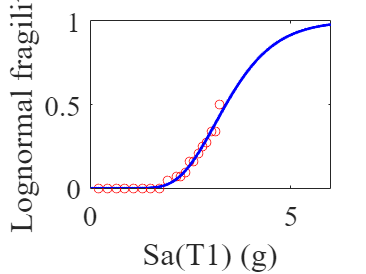

hold on;
IM_levels = 0.01:0.01:6.0;
probability = logncdf(IM_levels, log(theta), beta);
plot(IM_levels, probability, 'linewidth', 2, 'color', 'blue');
hold off;
xlabel('Sa(T1) (g)', 'fontname', 'times new roman', 'fontsize', font_size);
ylabel('Lognormal fragility', 'fontname', 'times new roman', 'fontsize', font_size);
% legend('Empirical collapse probability', 'Lognormal fragility');
set(gca, 'fontname', 'times new roman', 'fontsize', font_size);
box on;


cd (currentDir)

## Plot Collaborative filtering based results

% figure(2)
% font_size = 20;
% boxplot((thetaList(1:7,:))', 'whisker', inf);
% xlabel('Threshold (T)', 'fontname', 'times new roman', 'fontsize', font_size);
% ylabel('Median collapse capacity (g)', 'fontname', 'times new roman', 'fontsize', font_size);
% % set(gca,'XTickLabel',{'0','5', '10', '15', '20', '25', '30', '35', '40', '45', '50'});
% set(gca,'XTickLabel',{'0','5', '10', '15', '20', '25', '30'});
% set(gca, 'fontname', 'times new roman', 'fontsize', font_size);


% figure(3)
% font_size = 20;
% boxplot((betaList(1:7,:))', 'whisker', inf);
% xlabel('Threshold (T)', 'fontname', 'times new roman', 'fontsize', font_size);
% ylabel('Standard deviation', 'fontname', 'times new roman', 'fontsize', font_size);
% % set(gca,'XTickLabel',{'0','5', '10', '15', '20', '25', '30', '35', '40', '45', '50'});
% set(gca,'XTickLabel',{'0','5', '10', '15', '20', '25', '30'});
% set(gca, 'fontname', 'times new roman', 'fontsize', font_size);

cd(targetDir)
finalTheta = [TList', thetaList];
finalBeta = [TList', betaList];
writematrix(finalTheta, strcat('N', num2str(N), 'thetaList.csv'));
writematrix(finalBeta, strcat('N', num2str(N), 'betaList.csv'));

cd (currentDir)
